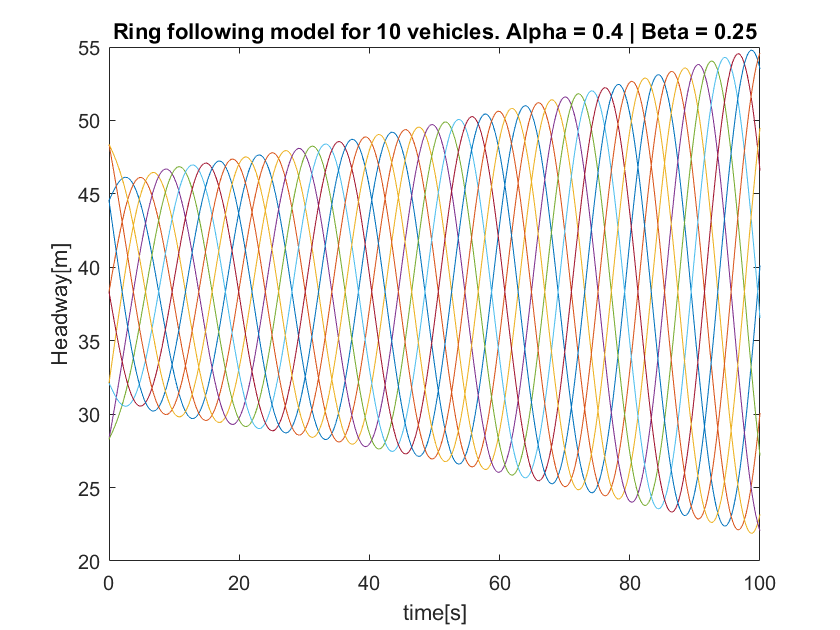

%HW2_Q3 Connected

clear all

N = 10; %Number of Vehicles in the Ring
vmax = 30;
kappa = 0.6;
hstop = 5;
hgo = hstop + vmax/kappa;
tstart = 0;
tend = 100;
tdelta = 0.1;
vstar = 20;
hstar = vstar/kappa + hstop;
alpha = 0.4;
beta = 0.25;
k = 1;
A = 5;
omega = (alpha +2*beta)*tan(k*pi/N);

%initial conditions
%Important quantity in ring conguration. Unlike platoon it will be different for each vehicle.

%Preallocating h0 and v0 for speed.
h0 = zeros(N,1);
v0 = zeros(N,1);
for i = 1:N
  h0(i) = hstar + (A/omega)*(sin((2*k*pi/N)*(i+1))-sin(2*k*pi*i/N));  
end
for i = 1:N
  v0(i) = vstar + A*cos(2*k*pi*i/N);  
end
y0 = [h0 ; v0];
y0 = y0';

tspan = tstart:tdelta:tend;
[t,y] = ode45(@(t,y)odefunc(t,y,kappa,alpha,beta,...
        hstop,hgo,vmax,vstar,N),tspan,y0);
  
headways = y(:,1:N);
velocities = y(:,N+1:2*N);

figure(1);
plot(t,headways);
xlabel('time[s]');
ylabel('Headway[m]');
title("Ring following model for "+N+...
    " vehicles. Alpha = "+alpha+" | Beta = "+beta);

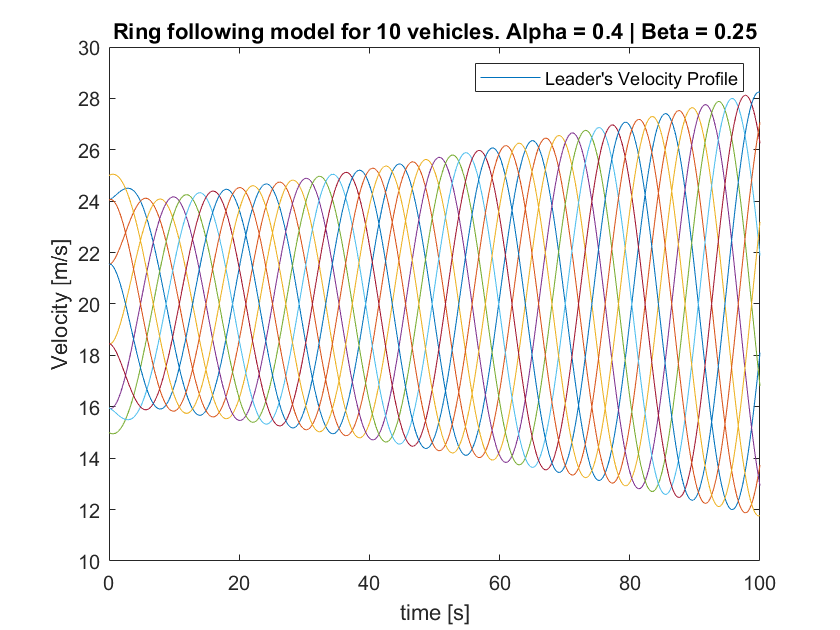


figure(2)
plot(t,velocities);
xlabel('time [s]');
ylabel('Velocity [m/s]');
title("Ring following model for "+N+...
    " vehicles. Alpha = "+alpha+" | Beta = "+beta);
legend('Leader''s Velocity Profile');

function dydt = odefunc(t,y,kappa,alpha,beta,hstop,hgo,vmax,vstar,follow_num)
%state [h1;h2;h3;.....;hfollow_num ; v1;v2;v3....;vfollow_num]
h = y(1:follow_num);
vF = y(follow_num+1:2*follow_num);  %velocity of all followers
vL = [vF(follow_num);
      vF(1:follow_num-1)] ;         %velocity of all the leaders,

%range policy
Vh = 0 + ((hstop<h)&(h<hgo)).*(kappa.*(h-hstop)) + (h>=hgo).*(vmax);

dydt = [(vL-vF);(alpha.*(Vh-vF)+beta.*(vL-vF))];

% dydt(1) = v_lead - y(follow_num + 1);
% 
% dydt(follow_num+1) = alpha*(0 +...
%                      ((hstop<y(1))&(y(1)<hgo))*(kappa*(y(1)-hstop))+(y(1)>=hgo)*(vmax)...
%                      - y(follow_num + 1))...
%                      + beta*(v_lead - y(follow_num + 1));  
%    
% i = 2;
% j = follow_num+2;
% while (((2<=i)&&(i<=follow_num)) && ((follow_num + 2<=j)&&(j<=2*follow_num)))
%     dydt(i) = y(i - 1) - y(i); 
%     dydt(j) = alpha*(0 +...
%               ((hstop<y(i))&(y(i)<hgo))*(kappa*(y(i)-hstop))+(y(i)>=hgo)*(vmax)...
%               - y(j))...
%               + beta*(y(j-1) - y(j));
%     i = i + 1;
%     j = j + 1;
% end
%     
% dydt = dydt';
end



